# Simulation of a composite active material

This example shows how to simulate a composite active material

## Setup the properties of the battery

We load the property of a composite silicon graphite electrode.

jsonstruct_composite_material = parseBattmoJson('ParameterData/BatteryCellParameters/LithiumIonBatteryCell/composite_silicon_graphite.json');

In this structure, we have the material property of two active materials, `ActiveMaterial1` and `ActiveMaterial2`.

flattenJsonStruct(jsonstruct_composite_material);

                                          parameter name                                                  parameter value        
    __________________________________________________________________________________________    _______________________________

    {'NegativeElectrode.Coating.activeMaterialModelSetup.composite'                          }    {[                          1]}
    {'NegativeElectrode.Coating.ActiveMaterial1.specificHeatCapacity'                        }    {[                        632]}
    {'NegativeElectrode.Coating.ActiveMaterial1.heatCapacity'                                }    {[                     632000]}
    {'NegativeElectrode.Coating.ActiveMaterial1.thermalConductivity'                         }    {[                     1.0400]}
    {'NegativeElectrode.Coating.ActiveMaterial1.electronicConductivity'                      }    {[                        100]}
    {'NegativeElectrode.Coating.ActiveMaterial1.massFraction'                            

For the remaining properties, we load a standard data set

jsonstruct_cell = parseBattmoJson('ParameterData/BatteryCellParameters/LithiumIonBatteryCell/lithium_ion_battery_nmc_graphite.json');

We remove from this structure active material field. This step is not necessary but is cleaner and we avoid a warning.

jsonstruct_cell = removeJsonStructField(jsonstruct_cell, {'NegativeElectrode', 'Coating', 'ActiveMaterial'});

we load a 1d geometry

jsonfilename = fullfile('Examples', 'JsonDataFiles', 'geometry1d.json');
jsonstruct_geometry = parseBattmoJson(jsonfilename);

We merge the json structures

jsonstruct = mergeJsonStructs({jsonstruct_composite_material, ...
                               jsonstruct_cell              , ...
                               jsonstruct_geometry});

We do not consider the thermal model and remove the current collector. We also use a CV switch control.

jsonstruct.use_thermal                = false;
jsonstruct.include_current_collectors = false;

We define some shorcuts for the sub-models, for convenience

ne   = 'NegativeElectrode';
pe   = 'PositiveElectrode';
co   = 'Coating';
am1  = 'ActiveMaterial1';
am2  = 'ActiveMaterial2';
bd   = 'Binder';
ad   = 'ConductingAdditive';
sd   = 'SolidDiffusion';
itf  = 'Interface';
ctrl = 'Control';

## We modify some parameters

We adjust the mass fractions parameters of the active material in the negative electrode

jsonstruct = setJsonStructField(jsonstruct, {ne, co, am1, 'massFraction'}, 0.9, 'handleMisMatch', 'quiet');
jsonstruct = setJsonStructField(jsonstruct, {ne, co, am2, 'massFraction'}, 0.08, 'handleMisMatch', 'quiet');
jsonstruct = setJsonStructField(jsonstruct, {ne, co, bd , 'massFraction'}, 0.01, 'handleMisMatch', 'quiet');
jsonstruct = setJsonStructField(jsonstruct, {ne, co, ad , 'massFraction'}, 0.01, 'handleMisMatch', 'quiet');

## We run the simulations

output = runBatteryJson(jsonstruct);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am1_sd_massCons (cell) | ne_co_am1_sd_solidDiffusionEq (cell) | ne_co_am2_sd_massCons (cell) | ne_co_am2_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) |

## Plotting

We extract the voltage, current and time from the simulation output

states = output.states;
model  = output.model;

E    = cellfun(@(x) x.Control.E, states);
I    = cellfun(@(x) x.Control.I, states);
time = cellfun(@(x) x.time, states);

We plot the voltage and current

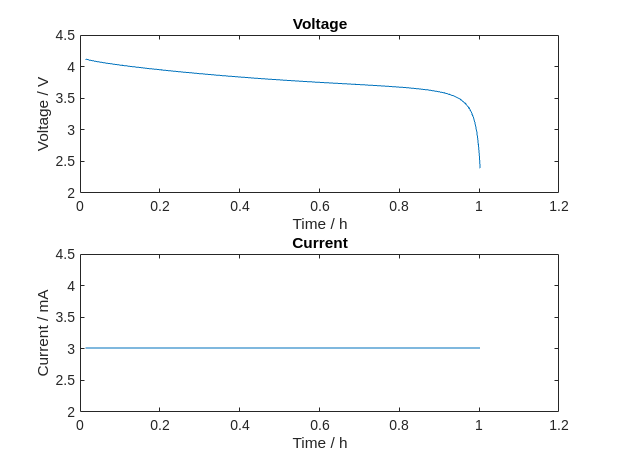

figure
subplot(2, 1, 1);
plot(time/hour, E);
xlabel('Time / h');
ylabel('Voltage / V');
title('Voltage')
subplot(2, 1, 2);
plot(time/hour, I/milli);
xlabel('Time / h');
ylabel('Current / mA');
title('Current')

We compute and plot the state of charges in the different material

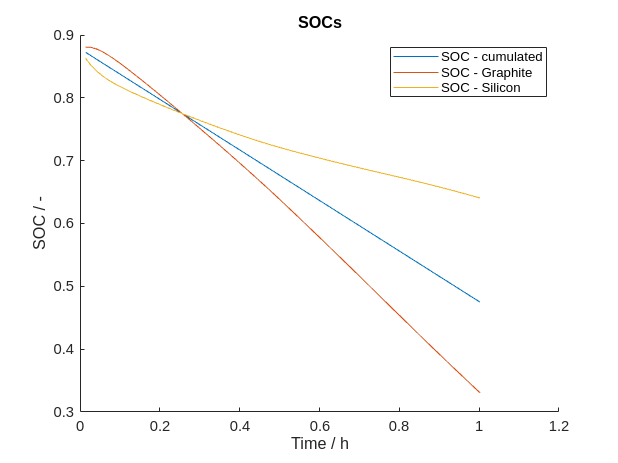

figure
hold on

for istate = 1 : numel(states)
    states{istate} = model.evalVarName(states{istate}, {ne, co, 'SOC'});
end

SOC  = cellfun(@(x) x.(ne).(co).SOC, states);
SOC1 = cellfun(@(x) x.(ne).(co).(am1).SOC, states);
SOC2 = cellfun(@(x) x.(ne).(co).(am2).SOC, states);

plot(time/hour, SOC, 'displayname', 'SOC - cumulated');
plot(time/hour, SOC1, 'displayname', 'SOC - Graphite');
plot(time/hour, SOC2, 'displayname', 'SOC - Silicon');

xlabel('Time / h');
ylabel('SOC / -');
title('SOCs')

legend show

## plot of the particle concentration distribution in the particle at the end time

We recover the state at the last time step

state = states{end};

We iterate over the two active materials. The first one is the graphite and the second one the silicon

ams = {am1, am2};

for iam = 1 : numel(ams)

    am = ams{iam};

    model_sd = model.(ne).(co).(am).(sd);
    state_sd = state.(ne).(co).(am).(sd);

We recover the concentration as an array. The column index corresponds to the spatial direction (here x as we are considering a 1D model) and the row index corresponds to the particle radia direction

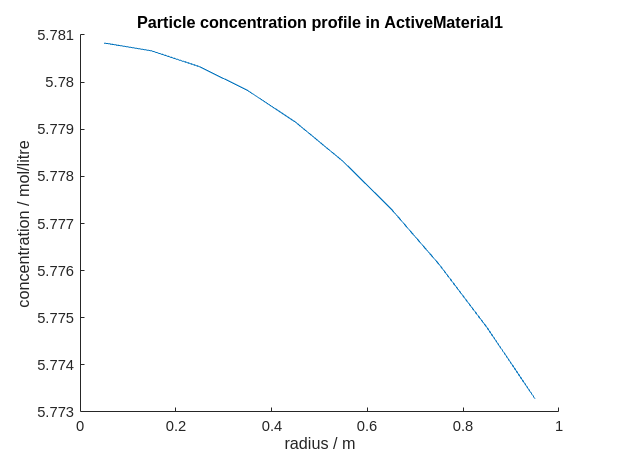

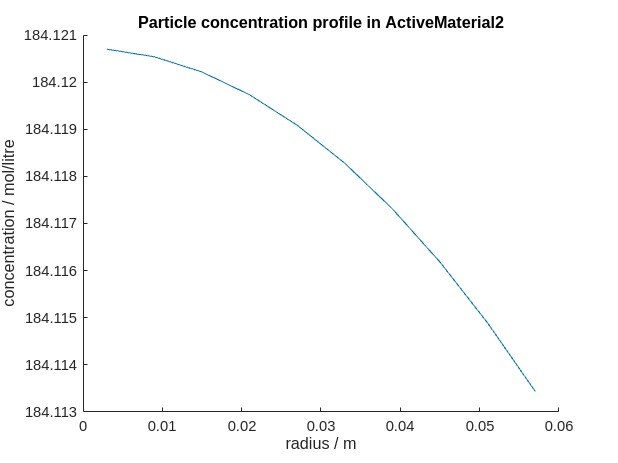

    c = model_sd.getParticleConcentrations(state_sd);
    r = model_sd.operators.radii;

    figure
    hold on

We plot the concentration distribution at the last point in the grid, which corresponds in this case to the closest to the positive electrode

    plot(r/(micro*meter), c(size(c, 1), :)/(mol/litre));
    title(sprintf('Particle concentration profile in %s', am));
    xlabel('radius / m');
    ylabel('concentration / mol/litre');
    
end

## Charge step

initstate = states{end};
jsonstruct.(ctrl).CRate = 1;
jsonstruct = setJsonStructField(jsonstruct, {'Control', 'controlPolicy'}, 'CCCharge', 'handleMisMatch', 'quiet');

jsonstruct.initializationSetup = 'given matlab object';

output = runBatteryJson(jsonstruct, 'initstate', initstate);

Solving timestep 001/100:                                            -> 50 Seconds, 399 Milliseconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am1_sd_massCons (cell) | ne_co_am1_sd_solidDiffusionEq (cell) | ne_co_am2_sd_massCons (cell) | ne_co_am2_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) |

|    2 |*1.36e-12               |*0.00e+00                    | 4.73e-02                     | 4.73e-02                             | 2.69e+01                     | 2.69e+01                             | 1.78e+00                | 3.07e+11                    | 3.07e+11                            | 2.20e+11                | 2.76e+11                | 2.76e+11              |


|    3 |*1.36e-12               |*0.00e+00                    | 9.80e-04                     | 9.80e-04                             | 5.13e-01                     | 5.13e-01                             | 3.42e-02                | 1.13e+11                    | 1.13e+11                            | 8.09e+10                | 1.02e+11                | 1.02e+11              |


|    4 |*9.20e-13               |*0.00e+00                    |*1.91e-07                     |*1.91e-07                             | 8.51e-05                     | 8.51e-05                             | 5.70e-06                | 4.16e+10                    | 4.16e+10                            | 2.98e+10                | 3.74e+10                | 3.74e+10              |
|    5 |*9.20e-13               |*0.00e+00                    |*1.01e-11                     |*1.01e-11                             |*6.46e-10                     |*6.58e-10                             |*5.00e-11                | 1.53e+10                    | 1.53e+10                            | 1.09e+10                | 1.38e+10                | 1.38e+10              |
|    6 |*1.36e-12               |*0.00e+00                    |*6.12e-12                     |*6.15e-12                             |*3.02e-10                     |*3.14e-10                             |*2.48e-11                | 5.63e+09              

## Visualisation

We concatenate the states we have computed

dischargeStates = states; % see previous assignement
chargeStates    = output.states; % assigned from last simulation output

allStates = vertcat(dischargeStates, chargeStates);

% We extract the voltage, current and time from the simulation output
E    = cellfun(@(x) x.Control.E, allStates);
I    = cellfun(@(x) x.Control.I, allStates);
time = cellfun(@(x) x.time, allStates);

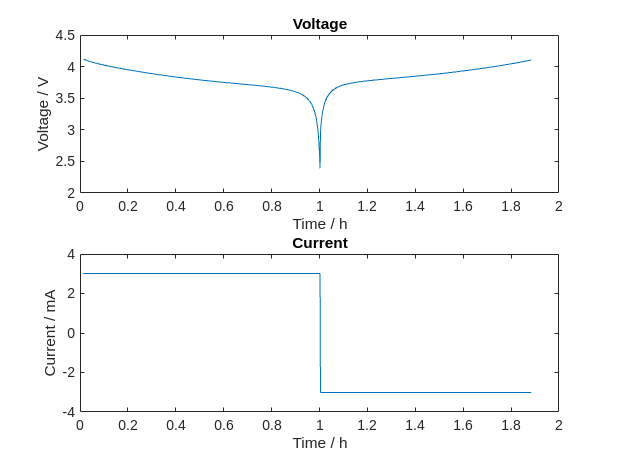

figure
subplot(2, 1, 1);
plot(time/hour, E);
xlabel('Time / h');
ylabel('Voltage / V');
title('Voltage')
subplot(2, 1, 2);
plot(time/hour, I/milli);
xlabel('Time / h');
ylabel('Current / mA');
title('Current')

We compute and plot the state of charges in the different material

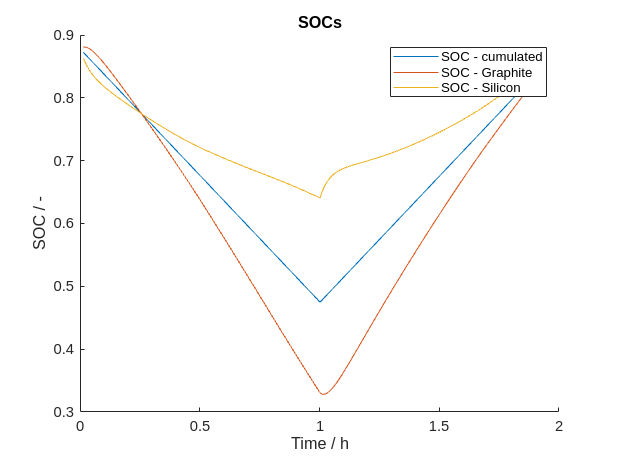

figure
hold on

for istate = 1 : numel(allStates)
    allStates{istate} = model.evalVarName(allStates{istate}, {ne, co, 'SOC'});
end

SOC  = cellfun(@(x) x.(ne).(co).SOC, allStates);
SOC1 = cellfun(@(x) x.(ne).(co).(am1).SOC, allStates);
SOC2 = cellfun(@(x) x.(ne).(co).(am2).SOC, allStates);

plot(time/hour, SOC, 'displayname', 'SOC - cumulated');
plot(time/hour, SOC1, 'displayname', 'SOC - Graphite');
plot(time/hour, SOC2, 'displayname', 'SOC - Silicon');

xlabel('Time / h');
ylabel('SOC / -');
title('SOCs')

legend show




%{
Copyright 2021-2024 SINTEF Industry, Sustainable Energy Technology
and SINTEF Digital, Mathematics & Cybernetics.

This file is part of The Battery Modeling Toolbox BattMo

BattMo is free software: you can redistribute it and/or modify
it under the terms of the GNU General Public License as published by
the Free Software Foundation, either version 3 of the License, or
(at your option) any later version.

BattMo is distributed in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the
GNU General Public License for more details.

You should have received a copy of the GNU General Public License
along with BattMo.  If not, see <http://www.gnu.org/licenses/>.
%}